
%% Part 1: System Parameters & Base Signals
% This section defines the core frequencies and generates the message 
% and carrier signals.

Fs = 10000;      % Sampling frequency (10 kHz)
Fc = 1000;       % Carrier frequency (1 kHz)
Fm = 100;        % Message frequency (100 Hz)

Am = 1;          % Message amplitude
Ac = 2;          % Carrier amplitude (Offset for AM)

t = 0 : 1/Fs : 0.05; % Time vector for 0.05 seconds

% Base Signals
m_t = Am * cos(2 * pi * Fm * t); 
c_t = Ac * cos(2 * pi * Fc * t); 

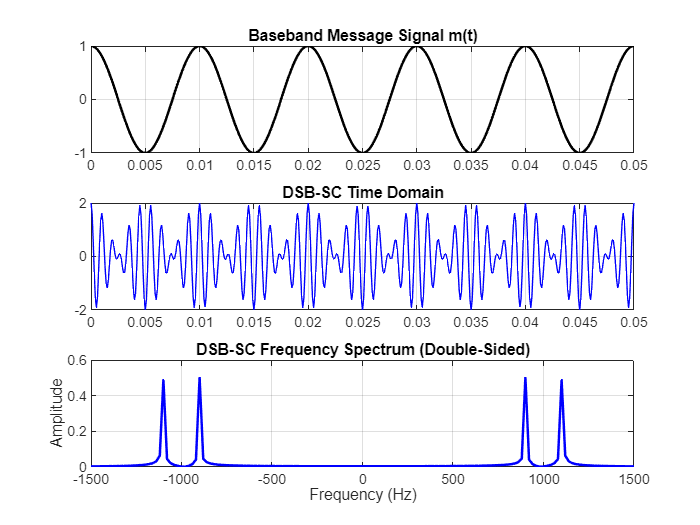


%% Part 2: Double Sideband Suppressed Carrier (DSB-SC)
% We use the modulate_dsb function to generate the signal, which 
% simply performs the mathematical multiplication m(t) * c(t).

% 1. Generate Signal using Function
s_dsb = modulate_dsb(m_t, c_t); 

% 2. --- Double-Sided FFT Calculation ---
L = length(s_dsb);
Y_dsb = abs(fftshift(fft(s_dsb))) / L;  % Compute FFT, shift 0 Hz to center, and normalize
f = linspace(-Fs/2, Fs/2, L);           % Create double-sided frequency vector

% 3. --- Plotting ---
figure;
subplot(3, 1, 1); 
plot(t, m_t, 'k', 'LineWidth', 1.5); 
title('Baseband Message Signal m(t)'); grid on;

subplot(3, 1, 2);
plot(t, s_dsb, 'b'); 
title('DSB-SC Time Domain'); grid on;

subplot(3, 1, 3);
plot(f, Y_dsb, 'b', 'LineWidth', 1.5);
title('DSB-SC Frequency Spectrum (Double-Sided)');
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([-1500 1500]); grid on;


%% Part 3: Standard Amplitude Modulation (AM)
% Standard AM adds a DC offset (the carrier amplitude) to the message 
% before multiplying by the carrier.

s_am = modulate_am(m_t, t, Fc, Ac)

s_am =     3.0000    2.4255    0.9246   -0.9216   -2.4016   -2.9511   -2.3702   -0.8976    0.8888    2.3011    2.8090    2.2414    0.8433   -0.8296   -2.1337   -2.5878   -2.0515   -0.7669    0.7496    1.9159    2.3090    1.8192    0.6759   -0.6568   -1.6688   -2.0000   -1.5672   -0.5793    0.5601    1.4168    1.6910    1.3202    0.4865   -0.4692   -1.1845   -1.4122   -1.1023   -0.4065    0.3928    0.9947    1.1910    0.9350    0.3472   -0.3384   -0.8658   -1.0489   -0.8344   -0.3145    0.3115    0.8106


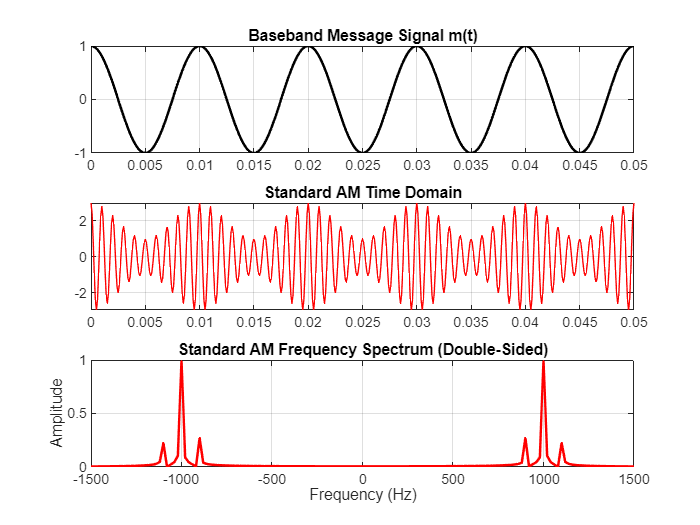



% --- Double-Sided FFT Calculation ---
L = length(s_am);
Y_am = abs(fftshift(fft(s_am))) / L;
f = linspace(-Fs/2, Fs/2, L);

% --- Plotting ---
figure;
subplot(3, 1, 1); 
plot(t, m_t, 'k', 'LineWidth', 1.5); 
title('Baseband Message Signal m(t)'); grid on;

subplot(3, 1, 2);
plot(t, s_am, 'r'); 
title('Standard AM Time Domain'); grid on;

subplot(3, 1, 3);
plot(f, Y_am, 'r', 'LineWidth', 1.5);
title('Standard AM Frequency Spectrum (Double-Sided)');
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([-1500 1500]); grid on;

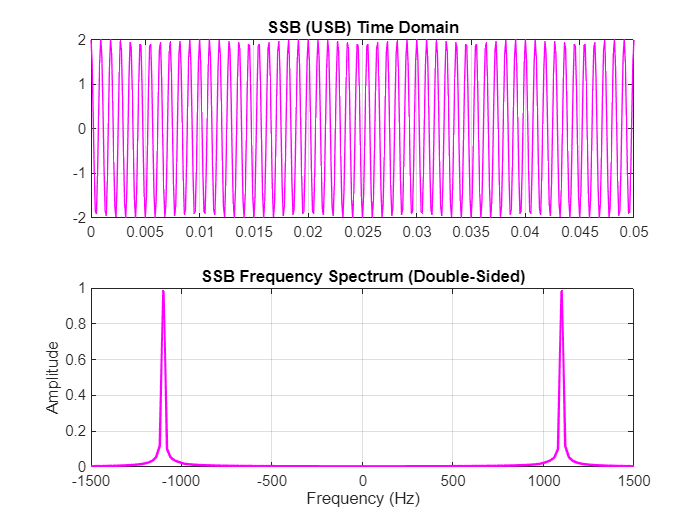

%% Part 4: Single Sideband (SSB)
% We use the Hilbert Transform (Phase Shift) method to isolate the Upper Sideband.
% The logic is now encapsulated in the modulate_ssb function for consistency.

% 1. Generate Signal using Function
s_ssb_usb = modulate_ssb(m_t, t, Fc, Ac);

% 2. --- Double-Sided FFT Calculation ---
L = length(s_ssb_usb);
Y_ssb = abs(fftshift(fft(s_ssb_usb))) / L;
f = linspace(-Fs/2, Fs/2, L);

% 3. --- Plotting ---
figure;
subplot(2, 1, 1);
    
title('SSB (USB) Time Domain'); grid on;

subplot(2, 1, 2);
plot(f, Y_ssb, 'm', 'LineWidth', 1.5);
title('SSB Frequency Spectrum (Double-Sided)');
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([-1500 1500]); grid on;

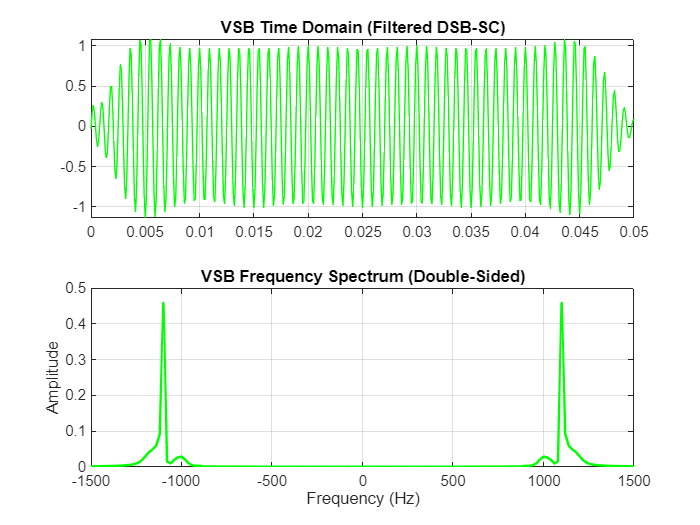


%% Part 5: Vestigial Sideband (VSB)
% We generate VSB by passing a DSB-SC signal through a bandpass filter.
% The modulate_vsb function handles the Butterworth filter design and 
% zero-phase filtering (filtfilt) to preserve a 20% vestige of the LSB.

% 1. Generate Signal using Function
s_vsb = modulate_vsb(m_t, c_t, Fs, Fc, Fm);

% 2. --- Double-Sided FFT Calculation ---
L = length(s_vsb);
Y_vsb = abs(fftshift(fft(s_vsb))) / L;
f = linspace(-Fs/2, Fs/2, L);

% 3. --- Plotting ---
figure;
subplot(2, 1, 1);
plot(t, s_vsb, 'g'); 
title('VSB Time Domain (Filtered DSB-SC)'); grid on;

subplot(2, 1, 2);
plot(f, Y_vsb, 'g', 'LineWidth', 1.5);
title('VSB Frequency Spectrum (Double-Sided)');
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([-1500 1500]); grid on;

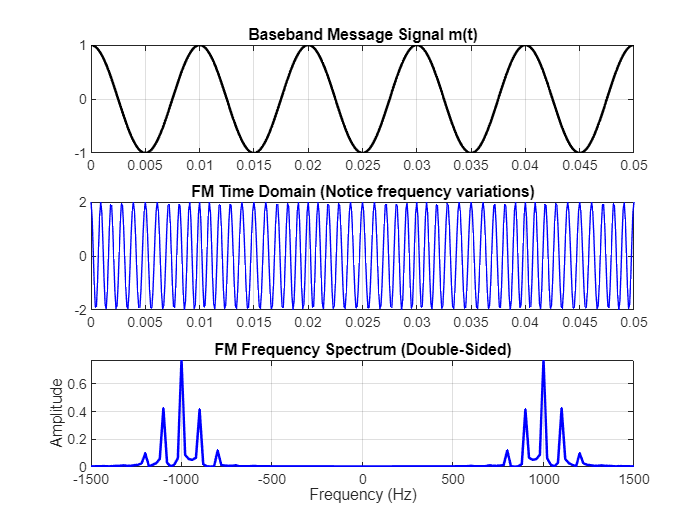

%% Part 6: Frequency Modulation (FM) with Double-Sided FFT
% FM changes the carrier frequency based on the message amplitude.
% We use the modulate_fm function which handles the message integration.

% 1. Frequency sensitivity / deviation constant
kf = 100; 

% 2. Generate Signal using Function
s_fm = modulate_fm(m_t, t, Fs, Fc, Ac, kf);

% 3. --- Double-Sided FFT Calculation ---
L = length(s_fm);
Y_fm = abs(fftshift(fft(s_fm))) / L;
f = linspace(-Fs/2, Fs/2, L);

% 4. --- Plotting ---
figure;
subplot(3, 1, 1);
plot(t, m_t, 'k', 'LineWidth', 1.5);
title('Baseband Message Signal m(t)'); grid on;

subplot(3, 1, 2);
plot(t, s_fm, 'b');
title('FM Time Domain (Notice frequency variations)'); grid on;

subplot(3, 1, 3);
plot(f, Y_fm, 'b', 'LineWidth', 1.5);
title('FM Frequency Spectrum (Double-Sided)');
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([-1500 1500]); grid on;

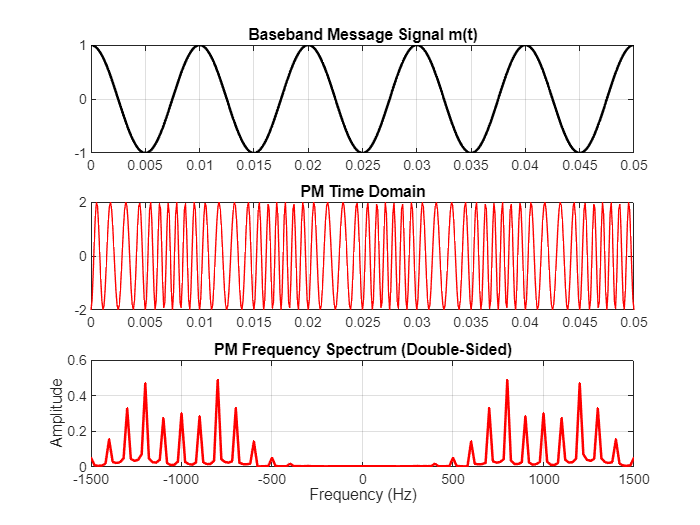



%% Part 7: Phase Modulation (PM) with Double-Sided FFT
% PM changes the instantaneous phase of the carrier based on the message.
% We use the modulate_pm function for a clean, consistent implementation.

% 1. Phase sensitivity constant (max shift of pi radians)
kp = pi; 

% 2. Generate Signal using Function
s_pm = modulate_pm(m_t, t, Fc, Ac, kp);

% 3. --- Double-Sided FFT Calculation ---
L = length(s_pm);
Y_pm = abs(fftshift(fft(s_pm))) / L;
f = linspace(-Fs/2, Fs/2, L);

% 4. --- Plotting ---
figure;
subplot(3, 1, 1);
plot(t, m_t, 'k', 'LineWidth', 1.5);
title('Baseband Message Signal m(t)'); grid on;

subplot(3, 1, 2);
plot(t, s_pm, 'r');
title('PM Time Domain'); grid on;

subplot(3, 1, 3);
plot(f, Y_pm, 'r', 'LineWidth', 1.5);
title('PM Frequency Spectrum (Double-Sided)');
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([-1500 1500]); grid on;

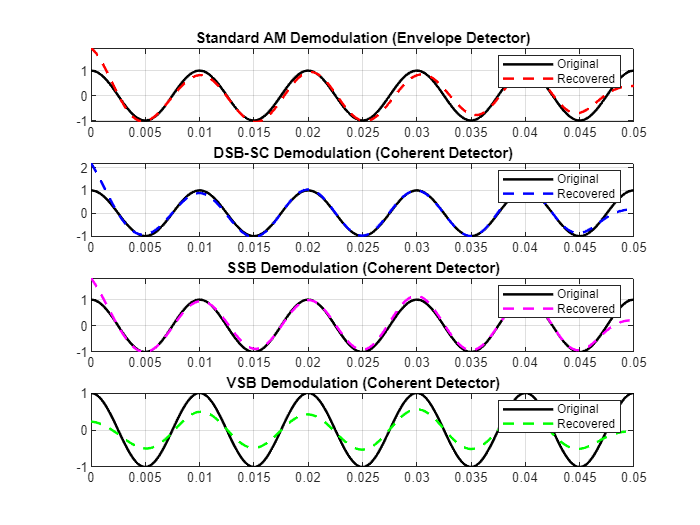

%% Part 8: Add Noise to the Modulated Signals (The Channel)
% We add noise to simulate a real-world transmission. 
SNR = 8; 

r_dsb = awgn(s_dsb, SNR, 'measured');
r_am  = awgn(s_am, SNR, 'measured');
r_ssb = awgn(s_ssb_usb, SNR, 'measured'); % FIXED: Matches Part 4 exactly
r_vsb = awgn(s_vsb, SNR, 'measured');
r_fm  = awgn(s_fm, SNR, 'measured');
r_pm  = awgn(s_pm, SNR, 'measured');

%% Part 9: Demodulate Amplitude Signals (AM, DSB, SSB, VSB)

m_rec_am  = demodulate_am(r_am, Fs);
m_rec_dsb = demodulate_coherent(r_dsb, t, Fc, Fs, Ac); % FIXED: Added Ac
m_rec_ssb = demodulate_coherent(r_ssb, t, Fc, Fs, Ac); % FIXED: Added Ac
m_rec_vsb = demodulate_coherent(r_vsb, t, Fc, Fs, Ac); % FIXED: Added Ac

figure;
% 1. Standard AM Plot
subplot(4, 1, 1);
plot(t, m_t, 'k', t, m_rec_am, 'r--', 'LineWidth', 1.5);
title('Standard AM Demodulation (Envelope Detector)'); 
legend('Original', 'Recovered'); grid on;

% 2. DSB-SC Plot
subplot(4, 1, 2);
plot(t, m_t, 'k', t, m_rec_dsb, 'b--', 'LineWidth', 1.5);
title('DSB-SC Demodulation (Coherent Detector)'); 
legend('Original', 'Recovered'); grid on;

% 3. SSB Plot
subplot(4, 1, 3);
plot(t, m_t, 'k', t, m_rec_ssb, 'm--', 'LineWidth', 1.5);
title('SSB Demodulation (Coherent Detector)'); 
legend('Original', 'Recovered'); grid on;

% 4. VSB Plot
subplot(4, 1, 4);
plot(t, m_t, 'k', t, m_rec_vsb, 'g--', 'LineWidth', 1.5);
title('VSB Demodulation (Coherent Detector)'); 
legend('Original', 'Recovered'); grid on;

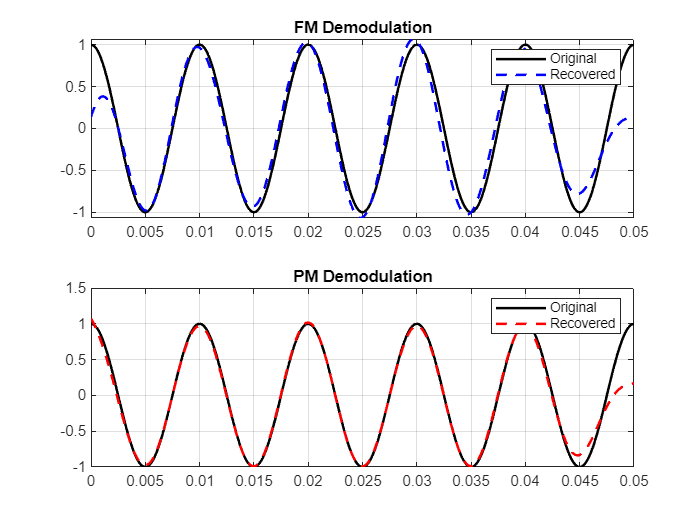


%% Part 10: Demodulate Angle Signals (FM, PM)
% We use the Hilbert transform (analytic signal) to extract the instantaneous 
% phase and frequency for demodulation.

m_rec_fm = demodulate_fm(r_fm, t, Fs, Fc, kf); % Using r_fm
m_rec_pm = demodulate_pm(r_pm, t, Fc, kp, Fs); % FIXED: Added Fs and using r_pm

figure;
subplot(2, 1, 1);
plot(t, m_t, 'k', t, m_rec_fm, 'b--', 'LineWidth', 1.5);
title('FM Demodulation'); 
legend('Original', 'Recovered'); grid on;

subplot(2, 1, 2);
plot(t, m_t, 'k', t, m_rec_pm, 'r--', 'LineWidth', 1.5);
title('PM Demodulation'); 
legend('Original', 'Recovered'); grid on;

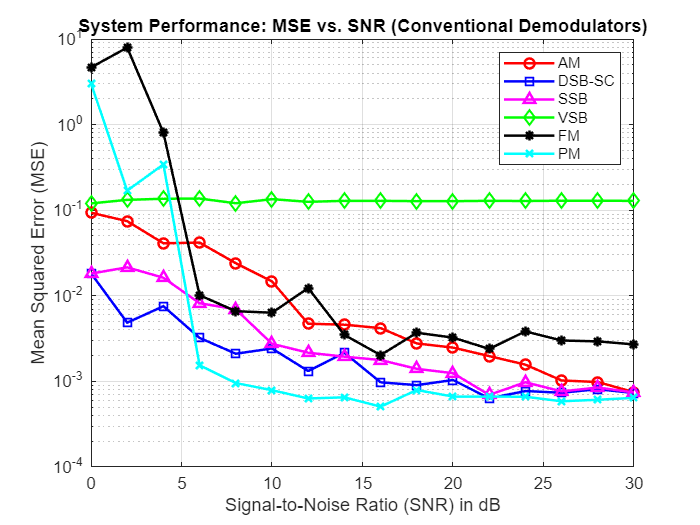

%% Part 11: Performance Analysis (MSE vs. SNR)
% We sweep through different Signal-to-Noise Ratios and calculate the 
% Mean Squared Error for each demodulation technique.

SNR_vec = 0:2:30; % Sweep from 0 dB to 30 dB in steps of 2
num_points = length(SNR_vec);

% Initialize arrays to hold the error values
mse_am  = zeros(1, num_points);
mse_dsb = zeros(1, num_points);
mse_ssb = zeros(1, num_points);
mse_vsb = zeros(1, num_points);
mse_fm  = zeros(1, num_points);
mse_pm  = zeros(1, num_points);

for i = 1:num_points
    current_snr = SNR_vec(i);
    
    % 1. Add noise for this specific SNR iteration
    r_am  = awgn(s_am, current_snr, 'measured');
    r_dsb = awgn(s_dsb, current_snr, 'measured');
    r_ssb = awgn(s_ssb_usb, current_snr, 'measured');
    r_vsb = awgn(s_vsb, current_snr, 'measured');
    r_fm  = awgn(s_fm, current_snr, 'measured');
    r_pm  = awgn(s_pm, current_snr, 'measured');
    
    % 2. Demodulate the noisy signals (FIXED ARGUMENTS HERE)
    m_rec_am  = demodulate_am(r_am, Fs);
    m_rec_dsb = demodulate_coherent(r_dsb, t, Fc, Fs, Ac); % Added Ac
    m_rec_ssb = demodulate_coherent(r_ssb, t, Fc, Fs, Ac); % Added Ac
    m_rec_vsb = demodulate_coherent(r_vsb, t, Fc, Fs, Ac); % Added Ac
    m_rec_fm  = demodulate_fm(r_fm, t, Fs, Fc, kf);
    m_rec_pm  = demodulate_pm(r_pm, t, Fc, kp, Fs);        % Added Fs
    
    % 3. Calculate Mean Squared Error (MSE) - WITH EDGE TRIMMING
    % We ignore the first 50 and last 50 samples to bypass filter transients
    trim = 50; 
    idx = trim : (length(m_t) - trim);
    
    mse_am(i)  = mean((m_t(idx) - m_rec_am(idx)).^2);
    mse_dsb(i) = mean((m_t(idx) - m_rec_dsb(idx)).^2);
    mse_ssb(i) = mean((m_t(idx) - m_rec_ssb(idx)).^2);
    mse_vsb(i) = mean((m_t(idx) - m_rec_vsb(idx)).^2);
    mse_fm(i)  = mean((m_t(idx) - m_rec_fm(idx)).^2);
    mse_pm(i)  = mean((m_t(idx) - m_rec_pm(idx)).^2);
end

% --- Plotting the Performance Curves ---
figure;
semilogy(SNR_vec, mse_am, 'r-o', 'LineWidth', 1.5); hold on;
semilogy(SNR_vec, mse_dsb, 'b-s', 'LineWidth', 1.5);
semilogy(SNR_vec, mse_ssb, 'm-^', 'LineWidth', 1.5);
semilogy(SNR_vec, mse_vsb, 'g-d', 'LineWidth', 1.5);
semilogy(SNR_vec, mse_fm, 'k-*', 'LineWidth', 1.5);
semilogy(SNR_vec, mse_pm, 'c-x', 'LineWidth', 1.5);

title('System Performance: MSE vs. SNR (Conventional Demodulators)');
xlabel('Signal-to-Noise Ratio (SNR) in dB');
ylabel('Mean Squared Error (MSE)');
legend('AM', 'DSB-SC', 'SSB', 'VSB', 'FM', 'PM');
grid on;

%% Part 12: Universal AI Data Generation
num_samples = 10000; %no of samples
sample_len = length(t);

X_data = zeros(num_samples, sample_len); 
Y_data = zeros(num_samples, sample_len); 

fprintf('Generating Universal Dataset... ');

Generating Universal Dataset... 


for i = 1:num_samples
    % 1. Randomize Parameters
    Fm_rand = 50 + (200-50)*rand();
    SNR_rand = 0 + (20-0)*rand();
    m_rand = Am * cos(2 * pi * Fm_rand * t);
    
    % 2. Randomly Pick a Modulation Type (1 to 6)
    mod_type = randi(6); 
    
    switch mod_type
        case 1, s_rand = modulate_am(m_rand, t, Fc, Ac);
        case 2, s_rand = modulate_dsb(m_rand, c_t);
        case 3, s_rand = modulate_ssb(m_rand, t, Fc, Ac);
        case 4, s_rand = modulate_vsb(m_rand, c_t, Fs, Fc, Fm);
        case 5, s_rand = modulate_fm(m_rand, t, Fs, Fc, Ac, kf);
        case 6, s_rand = modulate_pm(m_rand, t, Fc, Ac, kp);
    end
    
    % 3. Add Noise and Save
    X_data(i, :) = awgn(s_rand, SNR_rand, 'measured');
    Y_data(i, :) = m_rand;
end

fprintf('Done!\n');

Done!


save('Universal_AI_Data.mat', 'X_data', 'Y_data');

%% Part 13 & 14: AI Model Training
% 1. Reshape data for the CNN (Neural Networks expect specific dimensions)
% X_data needs to be [Samples x 1 x 1 x TimePoints] for 1D Image Input 
% or formatted for Sequence Input. Let's use the simplest 2D format for this net.
X_train = X_data; 
Y_train = Y_data;

% 2. Define Architecture
inputSize = size(X_train, 2);
layers = [
    featureInputLayer(inputSize, 'Name', 'input')
    
    fullyConnectedLayer(256, 'Name', 'fc1')
    reluLayer('Name', 'relu1')
    
    fullyConnectedLayer(512, 'Name', 'fc2')
    reluLayer('Name', 'relu2')
    
    fullyConnectedLayer(inputSize, 'Name', 'fc3')
    regressionLayer('Name', 'output')
];

% 3. Specify Options
options = trainingOptions('adam', ...
    'MaxEpochs', 100, ...
    'MiniBatchSize', 64, ...
    'Shuffle', 'every-epoch', ...
    'InitialLearnRate', 1e-3, ...
    'Plots', 'training-progress', ... % THIS SHOULD OPEN A WINDOW
    'Verbose', false);

% 4. START TRAINING
% If this runs correctly, a "Deep Learning Training Progress" window WILL pop up.
fprintf('Starting Training... (This should take a minute)\n');

Starting Training... (This should take a minute)


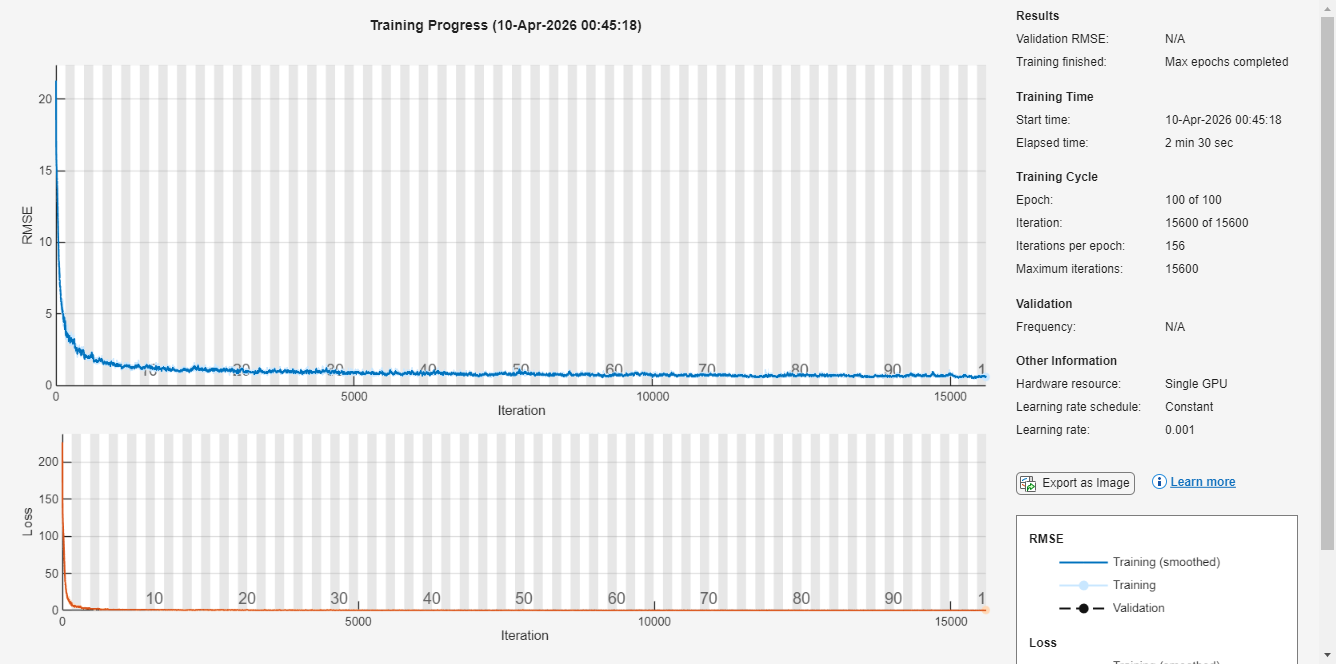

net = trainNetwork(X_train, Y_train, layers, options);

fprintf('Training Complete!\n');

Training Complete!


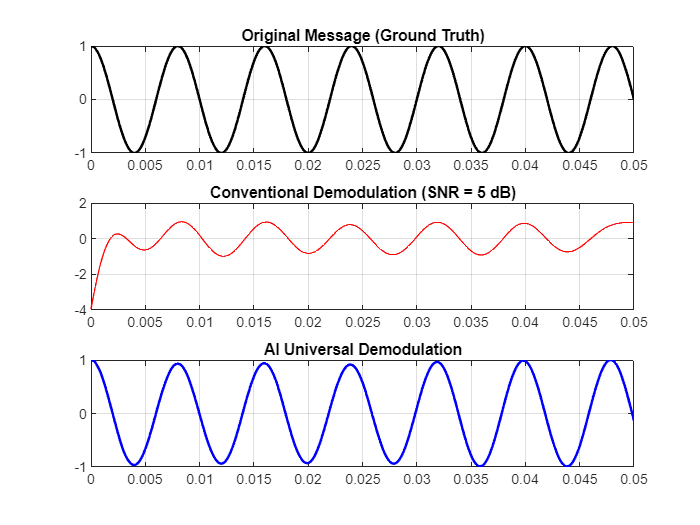

%% Part 15: Testing the AI Universal Demodulator

% 1. Create a brand new test signal (FM in this case)
Fm_test = 125; % A frequency the AI didn't specifically train on
m_test = Am * cos(2 * pi * Fm_test * t);
s_test = modulate_fm(m_test, t, Fs, Fc, Ac, kf);

% 2. Add heavy noise (SNR = 5 dB)
SNR_test = 5; 
r_test = awgn(s_test, SNR_test, 'measured');

% 3. Conventional Demodulation
m_recovered_conv = demodulate_fm(r_test, t, Fs, Fc, kf);

% 4. AI Demodulation
% The AI expects a row vector, so we pass r_test directly
m_recovered_ai = predict(net, r_test);

% 5. Compare the Results
figure;
subplot(3, 1, 1);
plot(t, m_test, 'k', 'LineWidth', 1.5);
title('Original Message (Ground Truth)'); grid on;

subplot(3, 1, 2);
plot(t, m_recovered_conv, 'r');
title(['Conventional Demodulation (SNR = ', num2str(SNR_test), ' dB)']); grid on;

subplot(3, 1, 3);
plot(t, m_recovered_ai, 'b', 'LineWidth', 1.5);
title('AI Universal Demodulation'); grid on;


% Calculate MSE for both
mse_conv = mean((m_test - m_recovered_conv).^2);
mse_ai = mean((m_test - m_recovered_ai).^2);

fprintf('Conventional MSE: %.6f\n', mse_conv);

Conventional MSE: 0.328894


fprintf('AI Demodulator MSE: %.6f\n', mse_ai);

AI Demodulator MSE: 0.005846


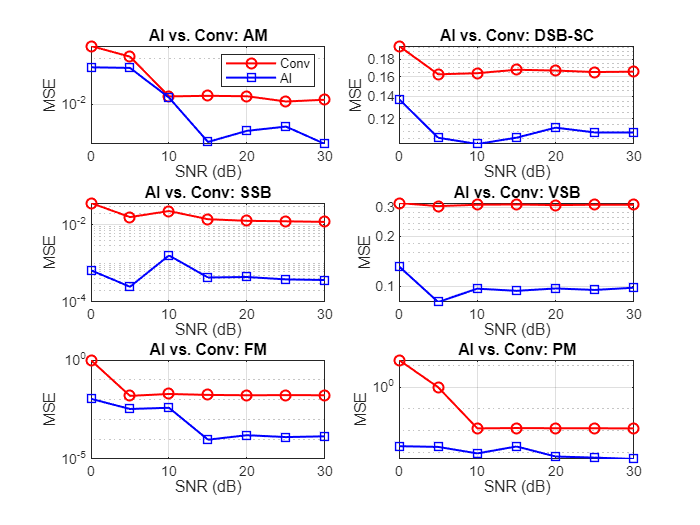

%% Part 16: Multi-Modulation Comparison (AI vs. Conventional)
SNR_vec_final = 0:5:30;
mod_names = {'AM', 'DSB-SC', 'SSB', 'VSB', 'FM', 'PM'};
figure('Name', 'Universal AI Performance Analysis');

for mod_type = 1:6
    mse_ai_vec = zeros(1, length(SNR_vec_final));
    mse_conv_vec = zeros(1, length(SNR_vec_final));
    
    for j = 1:length(SNR_vec_final)
        % 1. Setup Test Signal
        m_f = Am * cos(2 * pi * 125 * t); % Test frequency 125Hz
        
        % 2. Generate Modulated Signal based on type
        switch mod_type
            case 1, s_f = modulate_am(m_f, t, Fc, Ac);
            case 2, s_f = modulate_dsb(m_f, cos(2 * pi * Fc * t));
            case 3, s_f = modulate_ssb(m_f, t, Fc, Ac);
            case 4, s_f = modulate_vsb(m_f, cos(2 * pi * Fc * t), Fs, Fc, 125);
            case 5, s_f = modulate_fm(m_f, t, Fs, Fc, Ac, kf);
            case 6, s_f = modulate_pm(m_f, t, Fc, Ac, kp);
        end
        
        % 3. Add Noise
        r_f = awgn(s_f, SNR_vec_final(j), 'measured');
        
        % 4. Demodulate (AI)
        m_ai = predict(net, r_f);
        
        % 5. Demodulate (Conventional)
        switch mod_type
            case 1, m_conv = demodulate_am(r_f, Fs);
            case 2, m_conv = demodulate_coherent(r_f, t, Fc, Fs, Ac);
            case 3, m_conv = demodulate_coherent(r_f, t, Fc, Fs, Ac);
            case 4, m_conv = demodulate_coherent(r_f, t, Fc, Fs, Ac);
            case 5, m_conv = demodulate_fm(r_f, t, Fs, Fc, kf);
            case 6, m_conv = demodulate_pm(r_f, t, Fc, kp, Fs);
        end
        
        % 6. Calculate MSE (with 50-sample edge trim)
        idx = 50:(length(t)-50);
        mse_ai_vec(j) = mean((m_f(idx) - m_ai(idx)).^2);
        mse_conv_vec(j) = mean((m_f(idx) - m_conv(idx)).^2);
    end
    
    % 7. Plotting each modulation in its own subplot
    subplot(3, 2, mod_type);
    semilogy(SNR_vec_final, mse_conv_vec, 'r-o', 'LineWidth', 1.2); hold on;
    semilogy(SNR_vec_final, mse_ai_vec, 'b-s', 'LineWidth', 1.2);
    title(['AI vs. Conv: ', mod_names{mod_type}]);
    xlabel('SNR (dB)'); ylabel('MSE');
    if mod_type == 1, legend('Conv', 'AI'); end
    grid on;
end

%% Part 16 & 17: Performance Audit & Final Summary Table
SNR_vec_final = 0:5:30;
mod_names = {'AM', 'DSB-SC', 'SSB', 'VSB', 'FM', 'PM'};

% Initialize a matrix to store results for the final table
% Columns: [Avg Improvement %, Avg Accuracy Factor]
summary_results = zeros(6, 2);

fprintf('Running final performance audit... ');

Running final performance audit... 


for mod_type = 1:6
    mse_ai_temp = zeros(1, length(SNR_vec_final));
    mse_conv_temp = zeros(1, length(SNR_vec_final));
    
    for j = 1:length(SNR_vec_final)
        % 1. Setup Test Signal (125Hz)
        m_f = Am * cos(2 * pi * 125 * t); 
        
        % 2. Generate Modulated Signal
        switch mod_type
            case 1, s_f = modulate_am(m_f, t, Fc, Ac);
            case 2, s_f = modulate_dsb(m_f, cos(2 * pi * Fc * t));
            case 3, s_f = modulate_ssb(m_f, t, Fc, Ac);
            case 4, s_f = modulate_vsb(m_f, cos(2 * pi * Fc * t), Fs, Fc, 125);
            case 5, s_f = modulate_fm(m_f, t, Fs, Fc, Ac, kf);
            case 6, s_f = modulate_pm(m_f, t, Fc, Ac, kp);
        end
        
        r_f = awgn(s_f, SNR_vec_final(j), 'measured');
        
        % 3. AI Prediction
        m_ai = predict(net, r_f);
        
        % 4. Conventional Demodulation
        switch mod_type
            case 1, m_conv = demodulate_am(r_f, Fs);
            case 2, m_conv = demodulate_coherent(r_f, t, Fc, Fs, Ac);
            case 3, m_conv = demodulate_coherent(r_f, t, Fc, Fs, Ac);
            case 4, m_conv = demodulate_coherent(r_f, t, Fc, Fs, Ac);
            case 5, m_conv = demodulate_fm(r_f, t, Fs, Fc, kf);
            case 6, m_conv = demodulate_pm(r_f, t, Fc, kp, Fs);
        end
        
        % 5. MSE Calculation (with trimming)
        idx = 50:(length(t)-50);
        mse_ai_temp(j) = mean((m_f(idx) - m_ai(idx)).^2);
        mse_conv_temp(j) = mean((m_f(idx) - m_conv(idx)).^2);
    end
    
    % Store the averages for the final report
    summary_results(mod_type, 1) = mean(((mse_conv_temp - mse_ai_temp) ./ mse_conv_temp) * 100);
    summary_results(mod_type, 2) = mean(mse_conv_temp ./ mse_ai_temp);
end

fprintf('Done!\n\n');

Done!




% --- FINAL FORMATTED OUTPUT SECTION ---
fprintf('============================================================\n');

fprintf('        UNIVERSAL AI DEMODULATOR PERFORMANCE REPORT        \n');

        UNIVERSAL AI DEMODULATOR PERFORMANCE REPORT        


fprintf('============================================================\n');

fprintf('%-12s | %-22s | %-15s\n', 'Modulation', 'Avg. Improvement (%)', 'Accuracy Gain');

Modulation   | Avg. Improvement (%)   | Accuracy Gain  


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------



for i = 1:6
    fprintf('%-12s | %-21.2f%% | %-14.2fx\n', ...
            mod_names{i}, summary_results(i, 1), summary_results(i, 2));
end

AM           | 83.67                % | 26.76         x
DSB-SC       | 33.31                % | 1.51          x
SSB          | 81.39                % | 15.53         x
VSB          | 66.04                % | 3.01          x
FM           | 95.05                % | 171.10        x
PM           | 93.86                % | 26.40         x


fprintf('============================================================\n');


% =========================================================================
% DEMODULATION FUNCTIONS (CORRECTED FOR SCALING AND FILTERING)
% =========================================================================

function m_rec = demodulate_am(r_t, Fs)
    % AM Demodulator: Envelope Detector
    rectified = abs(r_t);
    f_cutoff = 150; 
    [b, a] = butter(5, f_cutoff/(Fs/2), 'low');
    m_rec = filtfilt(b, a, rectified);
    
    % Correct the 2/pi scaling factor introduced by full-wave rectification
    m_rec = m_rec * (pi / 2);
    m_rec = m_rec - mean(m_rec);
end

function m_rec = demodulate_coherent(r_t, t, Fc, Fs, Ac)
    % Coherent Demodulator for DSB-SC, SSB, and VSB
    v_t = r_t .* cos(2 * pi * Fc * t);
    
    f_cutoff = 150; 
    [b, a] = butter(5, f_cutoff/(Fs/2), 'low');
    m_rec = filtfilt(b, a, v_t);
    
    % Multiply by 2 to counter the cosine mixing, and divide by Ac 
    m_rec = (m_rec * 2) / Ac;
end

function m_rec = demodulate_fm(r_t, t, Fs, Fc, kf)
    % FM Demodulator
    z = hilbert(r_t);
    inst_phase = unwrap(angle(z));
    inst_freq = diff(inst_phase) * Fs / (2 * pi);
    inst_freq = [inst_freq, inst_freq(end)]; 
    m_rec_raw = (inst_freq - Fc) / kf;
    
    % MUST add a Low-Pass Filter to remove parabolic noise
    f_cutoff = 150; 
    [b, a] = butter(5, f_cutoff/(Fs/2), 'low');
    m_rec = filtfilt(b, a, m_rec_raw);
end

function m_rec = demodulate_pm(r_t, t, Fc, kp, Fs)
    % PM Demodulator
    z = hilbert(r_t);
    inst_phase = unwrap(angle(z));
    m_rec_raw = (inst_phase - 2 * pi * Fc * t) / kp;
    m_rec_raw = m_rec_raw - mean(m_rec_raw);
    
    % MUST add a Low-Pass Filter to remove out-of-band phase noise
    f_cutoff = 150; 
    [b, a] = butter(5, f_cutoff/(Fs/2), 'low');
    m_rec = filtfilt(b, a, m_rec_raw);
end

% =========================================================================
% MODULATION FUNCTIONS (Place at the absolute bottom of the script)
% =========================================================================

function s_am = modulate_am(m_t, t, Fc, Ac)
    % Standard AM: (Ac + m(t)) * cos(wc*t)
    s_am = (Ac + m_t) .* cos(2 * pi * Fc * t);
end

function s_dsb = modulate_dsb(m_t, c_t)
    % DSB-SC: m(t) * c_t
    s_dsb = m_t .* c_t;
end

function s_ssb = modulate_ssb(m_t, t, Fc, Ac)
    % SSB-USB using the Phase Shift (Hilbert) method
    % s(t) = m(t)cos(wc*t) - m_hat(t)sin(wc*t)
    m_hat = imag(hilbert(m_t)); 
    s_ssb = (m_t .* (Ac * cos(2 * pi * Fc * t))) - (m_hat .* (Ac * sin(2 * pi * Fc * t)));
end

function s_vsb = modulate_vsb(m_t, c_t, Fs, Fc, Fm)
    % VSB: DSB-SC signal passed through a sideband filter
    s_dsb = m_t .* c_t;
    f_vestige = Fc - (0.2 * Fm); 
    f_upper_edge = Fc + (2 * Fm); 
    [b, a] = butter(4, [f_vestige, f_upper_edge]/(Fs/2), 'bandpass');
    % Use filtfilt to avoid phase shift errors in MSE calculations
    s_vsb = filtfilt(b, a, s_dsb);
end

function s_fm = modulate_fm(m_t, t, Fs, Fc, Ac, kf)
    % FM: Ac * cos(wc*t + 2*pi*kf*integral(m(t)))
    integral_m = cumsum(m_t) / Fs; 
    s_fm = Ac * cos(2 * pi * Fc * t + 2 * pi * kf * integral_m);
end

function s_pm = modulate_pm(m_t, t, Fc, Ac, kp)
    % PM: Ac * cos(wc*t + kp*m(t))
    s_pm = Ac * cos(2 * pi * Fc * t + kp * m_t);
end